%% ESPACIO DE ESTADOS Y OBSERVADOR PARA DOS TANQUES ACOPLADOS
% Este script:
% 1. Carga los parámetros guardados en parametros_tanques.mat
% 2. Construye las matrices A, B, C y D
% 3. Forma el sistema en espacio de estados
% 4. Revisa controlabilidad y observabilidad
% 5. Diseña un observador de Luenberger
% 6. Simula estados reales y estimados

clear; clc; close all;

%% 1) CARGAR PARÁMETROS DEL SISTEMA
if ~isfile('parametros_tanques.mat')
    error(['No se encontró el archivo parametros_tanques.mat. ' ...
           'Primero ejecuta el Live Script de cálculo de R1 y R2.']);
end

load('parametros_tanques.mat');

if ~exist('R1','var') || ~exist('R2','var') || ~exist('A_tanque','var')
    error('Faltan variables necesarias en parametros_tanques.mat');
end

A_t = A_tanque;

fprintf('=====================================================\n');

fprintf('   ESPACIO DE ESTADOS Y OBSERVADOR - DOS TANQUES\n');

   ESPACIO DE ESTADOS Y OBSERVADOR - DOS TANQUES


fprintf('=====================================================\n');

fprintf('Área del tanque A = %.6f m^2\n', A_t);

Área del tanque A = 0.022500 m^2


fprintf('R1 = %.6f s/m^2\n', R1);

R1 = 722.630956 s/m^2


fprintf('R2 = %.6f s/m^2\n', R2);

R2 = 1013.846545 s/m^2


fprintf('=====================================================\n\n');


%% 2) CONSTRUIR MATRICES A, B, C, D
% Estados:
% x1 = h1 -> nivel del tanque 1
% x2 = h2 -> nivel del tanque 2
%
% Entrada:
% u = qin -> caudal de entrada
%
% Salida medida:
% y = h2

A = [ -1/(A_t*R1),              1/(A_t*R1);
       1/(A_t*R1),  -(1/(A_t*R1) + 1/(A_t*R2)) ];

B = [1/A_t;
     0];

C = [0 1];

D = 0;

disp('Matriz A:');

Matriz A:


disp(A);

   -0.0615    0.0615
    0.0615   -0.1053




disp('Matriz B:');

Matriz B:


disp(B);

   44.4444
         0




disp('Matriz C:');

Matriz C:


disp(C);

     0     1




disp('Matriz D:');

Matriz D:


disp(D);

     0




%% 3) CREAR EL SISTEMA EN ESPACIO DE ESTADOS
sys_ss = ss(A,B,C,D);

disp('Sistema en espacio de estados:');

Sistema en espacio de estados:


sys_ss


sys_ss =
 
  A = 
            x1       x2
   x1  -0.0615   0.0615
   x2   0.0615  -0.1053
 
  B = 
          u1
   x1  44.44
   x2      0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



%% 4) REVISAR CONTROLABILIDAD
Co = ctrb(A,B);
rango_Co = rank(Co);

fprintf('---------------------------------------------\n');

---------------------------------------------


fprintf('ANÁLISIS DE CONTROLABILIDAD\n');

ANÁLISIS DE CONTROLABILIDAD


fprintf('Rango de la matriz de controlabilidad = %d\n', rango_Co);

Rango de la matriz de controlabilidad = 2


fprintf('Número de estados = %d\n', size(A,1));

Número de estados = 2



if rango_Co == size(A,1)
    fprintf('El sistema es completamente controlable.\n');
else
    fprintf('El sistema NO es completamente controlable.\n');
end

El sistema es completamente controlable.


fprintf('---------------------------------------------\n\n');

---------------------------------------------




%% 5) REVISAR OBSERVABILIDAD
Ob = obsv(A,C);
rango_Ob = rank(Ob);

fprintf('---------------------------------------------\n');

---------------------------------------------


fprintf('ANÁLISIS DE OBSERVABILIDAD\n');

ANÁLISIS DE OBSERVABILIDAD


fprintf('Rango de la matriz de observabilidad = %d\n', rango_Ob);

Rango de la matriz de observabilidad = 2


fprintf('Número de estados = %d\n', size(A,1));

Número de estados = 2



if rango_Ob == size(A,1)
    fprintf('El sistema es completamente observable.\n');
else
    fprintf('El sistema NO es completamente observable.\n');
end

El sistema es completamente observable.


fprintf('---------------------------------------------\n\n');

---------------------------------------------




%% 6) POLOS DE LA PLANTA
polos_planta = eig(A);

disp('Polos de la planta en espacio de estados:');

Polos de la planta en espacio de estados:


disp(polos_planta);

   -0.1487
   -0.0181



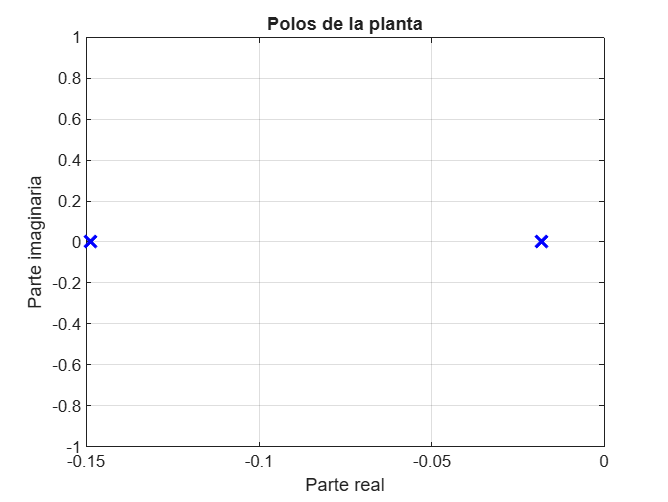


figure;
plot(real(polos_planta), imag(polos_planta), 'bx', 'MarkerSize', 10, 'LineWidth', 2);
grid on;
title('Polos de la planta');
xlabel('Parte real');
ylabel('Parte imaginaria');


%% 7) DISEÑO DEL OBSERVADOR DE LUENBERGER
% El observador debe ser más rápido que la planta.
% Regla práctica: entre 3 y 5 veces más rápido.
% Aquí se usarán polos del observador 4 veces más rápidos.

factor_observador = 8;
polos_obs = factor_observador * polos_planta;

% Como los polos de la planta son negativos, multiplicarlos por 4
% los deja más a la izquierda (más rápidos).

L = place(A', C', polos_obs)';
% Se usa la dualidad: place(A',C',...) y luego se transpone

disp('Polos deseados del observador:');

Polos deseados del observador:


disp(polos_obs);

   -1.1897
   -0.1450




disp('Ganancia del observador L:');

Ganancia del observador L:


disp(L);

    1.5938
    1.1679




%% 8) SISTEMA ERROR DEL OBSERVADOR
% e_dot = (A - L*C)e

A_obs = A - L*C;

disp('Matriz A-LC del observador:');

Matriz A-LC del observador:


disp(A_obs);

   -0.0615   -1.5323
    0.0615   -1.2733




polos_error_obs = eig(A_obs);

disp('Polos del error del observador:');

Polos del error del observador:


disp(polos_error_obs);

   -0.1450
   -1.1897



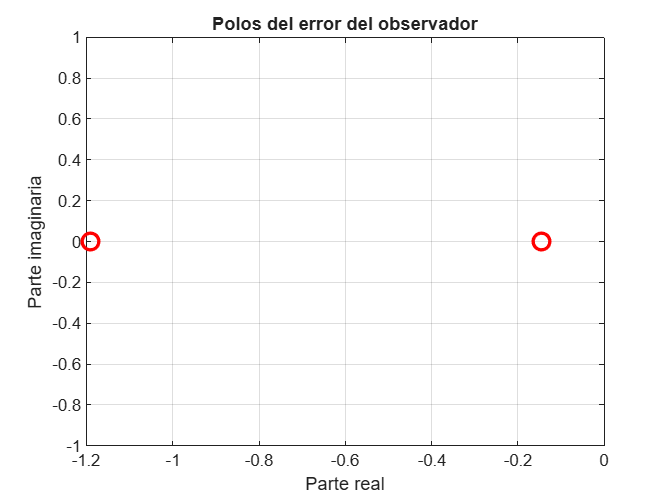


figure;
plot(real(polos_error_obs), imag(polos_error_obs), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
grid on;
title('Polos del error del observador');
xlabel('Parte real');
ylabel('Parte imaginaria');

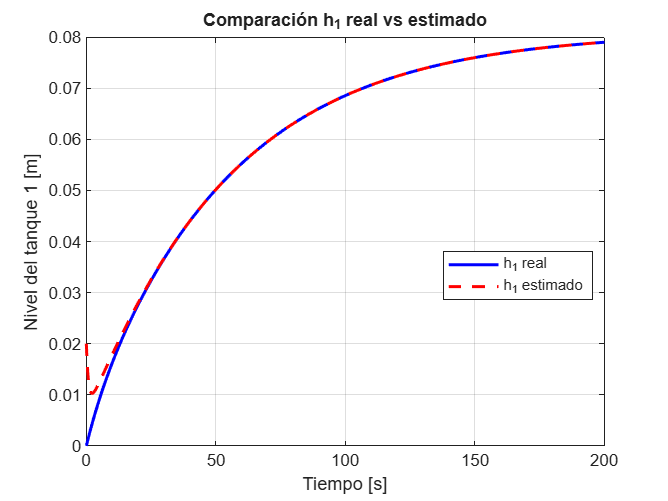


%% 9) SIMULACIÓN DEL SISTEMA REAL
% Vamos a simular una entrada constante de caudal
% y comparar estados reales vs estimados.

Qmax_Lh = 240;                       % [L/h]
Qmax = (Qmax_Lh/1000)/3600;          % [m^3/s]
fraccion_caudal = 0.70;              % 70% del caudal máximo
qin = fraccion_caudal * Qmax;        % [m^3/s]

t = 0:0.1:200;
u = qin * ones(size(t));

% Condiciones iniciales del sistema real
x0_real = [0; 0];

[y_real, t_real, x_real] = lsim(sys_ss, u, t, x0_real);

%% 10) SIMULACIÓN DEL OBSERVADOR
% Observador:
% xhat_dot = A*xhat + B*u + L(y - C*xhat)

% Para simularlo, armamos el sistema extendido:
%
% [x_dot   ] = [ A      0   ] [x    ] + [B]u
% [xhat_dot]   [ L*C  A-L*C ] [xhat ]   [B]

A_ext = [A,             zeros(size(A));
         L*C,           A - L*C];

B_ext = [B;
         B];

% La salida extendida la dejamos para recuperar estados
C_ext = eye(4);
D_ext = zeros(4,1);

sys_ext = ss(A_ext, B_ext, C_ext, D_ext);

% Condiciones iniciales:
% reales distintas de cero si quieres probar
% estimadas inicialmente diferentes para ver convergencia
x0_ext = [0; 0; 0.02; 0.01];
% [h1_real, h2_real, h1_estimado, h2_estimado]

[y_ext, t_ext, x_ext] = lsim(sys_ext, u, t, x0_ext);

% Extraer estados reales y estimados
h1_real = x_ext(:,1);
h2_real = x_ext(:,2);
h1_est  = x_ext(:,3);
h2_est  = x_ext(:,4);

%% 11) GRAFICAR ESTADOS REALES VS ESTIMADOS
figure;
plot(t_ext, h1_real, 'b', 'LineWidth', 1.8); hold on;
plot(t_ext, h1_est, '--r', 'LineWidth', 1.8);
grid on;
title('Comparación h_1 real vs estimado');
xlabel('Tiempo [s]');
ylabel('Nivel del tanque 1 [m]');
legend('h_1 real', 'h_1 estimado', 'Location', 'best');

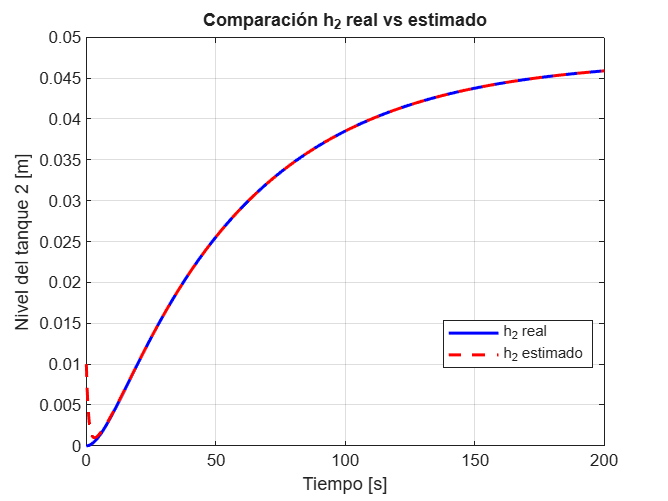


figure;
plot(t_ext, h2_real, 'b', 'LineWidth', 1.8); hold on;
plot(t_ext, h2_est, '--r', 'LineWidth', 1.8);
grid on;
title('Comparación h_2 real vs estimado');
xlabel('Tiempo [s]');
ylabel('Nivel del tanque 2 [m]');
legend('h_2 real', 'h_2 estimado', 'Location', 'best');

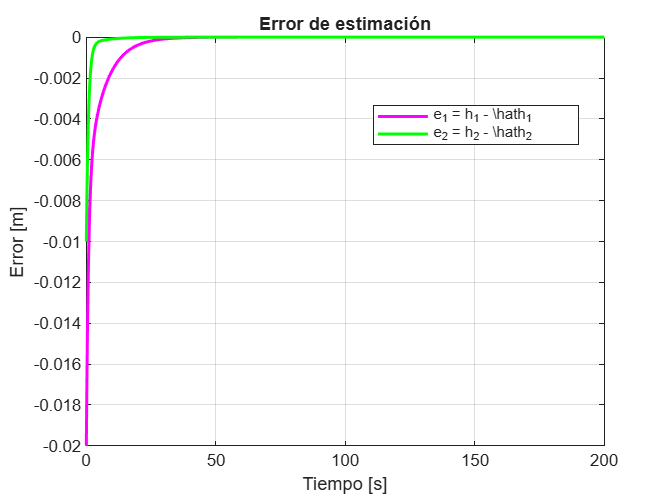


%% 12) ERROR DE ESTIMACIÓN
e1 = h1_real - h1_est;
e2 = h2_real - h2_est;

figure;
plot(t_ext, e1, 'm', 'LineWidth', 1.8); hold on;
plot(t_ext, e2, 'g', 'LineWidth', 1.8);
grid on;
title('Error de estimación');
xlabel('Tiempo [s]');
ylabel('Error [m]');
legend('e_1 = h_1 - \hat{h}_1', 'e_2 = h_2 - \hat{h}_2', 'Location', 'best');


%% 13) ERROR FINAL
fprintf('---------------------------------------------\n');

---------------------------------------------


fprintf('ERROR FINAL DE ESTIMACIÓN\n');

ERROR FINAL DE ESTIMACIÓN


fprintf('e1 final = %.8e m\n', e1(end));

e1 final = -1.83186799e-15 m


fprintf('e2 final = %.8e m\n', e2(end));

e2 final = -8.32667268e-17 m


fprintf('---------------------------------------------\n');

---------------------------------------------
